Це теоретичне моделювання **RLC-кола** (резистор, котушка, конденсатор) при вмиканні в розетку (постійний струм).

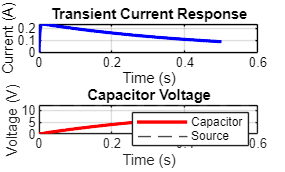

R = 50; 
L = 0.1;
C = 0.01;
V_source = 12;

t_span = [0 0.5];
initial_conditions = [0 0];
[t, results] = ode45(@(t, y) rlc_dynamics(t, y, R, L, C, V_source), t_span, initial_conditions);

Vc = results(:, 1);
I = results(:, 2);

figure; 

subplot(2, 1, 1);
plot(t, I, 'b-', 'LineWidth', 2);
grid on;
title('Transient Current Response'); % Текст буде чорним автоматично
ylabel('Current (A)');
xlabel('Time (s)');

subplot(2, 1, 2);
plot(t, Vc, 'r-', 'LineWidth', 2);
hold on;
yline(V_source, 'k--', 'Source Voltage');
hold off;
grid on;
title('Capacitor Voltage');
ylabel('Voltage (V)');
xlabel('Time (s)');
legend('Capacitor', 'Source'); % Легенда теж буде правильною


% --- 5. Функція ---
function dydt = rlc_dynamics(~, y, R, L, C, V)
    Vc = y(1);
    I = y(2);
    dydt = [I/C; (V - R*I - Vc)/L];
end

Це реальна поведінка **RC-кола** (тільки резистор і конденсатор, без котушки), на яке подають **імпульси** (прямокутний сигнал, тобто то є напруга, то немає).

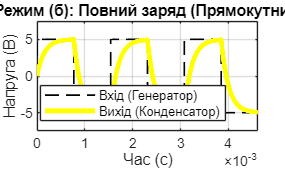

R = 70;            
C = 2.2e-6;       
tau = R * C;      
% Період дуже малий, частота висока
%mode = 1; 
% Випадок (б): Спотворений прямокутник
mode = 2;
% Випадок (в): Проміжний
%mode = 3;

switch mode
    case 1 
        f = 1 / (0.5 * tau);
        titlestr = 'Режим (а): Інтегрування (Трикутник)';
        
    case 2 
        f = 1 / (10 * tau); 
        titlestr = 'Режим (б): Повний заряд (Прямокутник)';
        
    case 3
        f = 1 / (2 * tau);
        titlestr = 'Режим (в): Проміжний стан';
end


T_period = 1/f;      
t_span = [0 3*T_period];
V_amp = 5;


Vin_func = @(t) V_amp * sign(sin(2*pi*f*t)); 

ode_fun = @(t, Vc) (Vin_func(t) - Vc) / (R * C);

options = odeset('MaxStep', T_period/1000); 

[t, Vc] = ode45(ode_fun, t_span, 0, options);


figure; 

% вхідний сигнал (пунктир)
fplot(Vin_func, t_span, 'k--', 'LineWidth', 1); 
hold on;

% напругу на конденсаторі 
plot(t, Vc, 'y-', 'LineWidth', 3); 

hold off;
grid on;
xlabel('Час (с)');
ylabel('Напруга (В)');
title(titlestr);
legend('Вхід (Генератор)', 'Вихід (Конденсатор)', 'Location', 'best');
ylim([-V_amp*1.5 V_amp*1.5]); % Трошки віддалити масштаб